# **Numerical Integration (Unequal) ***(not quadrative adapture)*

Function

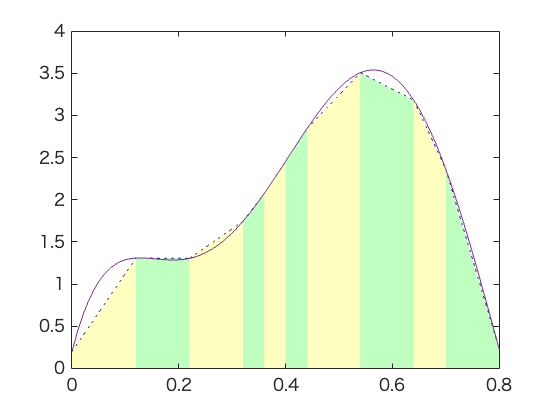

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8

format long
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p) % integrate polynomial equation (gives us the EXACT integration)

q = 1.0e+02 *

   0.666666666666667  -1.800000000000000   1.687500000000000  -0.666666666666667   0.125000000000000   0.002000000000000                   0


Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue =    1.640533333333333


Plot original function along with trapezoidal rule applied to each unequal segment

% data (unequal segments) used to integration with trapezoidal rule
x = [0 0.12 0.22 0.32 0.36 0.4 0.44 0.54 0.64 0.7 0.8]; % x array with unequal widths
y = f(x);
unequal = trapuneq(x, y) % correct answer (see Lec13 p.37)

unequal =    1.594800960000010


ns = length(x) - 1

ns =     10


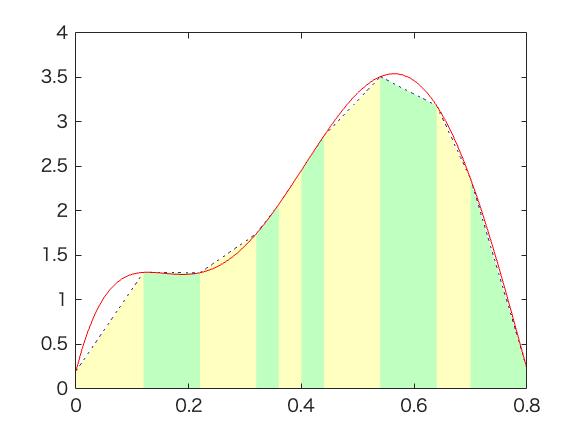


figure
color = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor', colors(mod(i,2) + 1), 'FaceAlpha', 0.25, 'EdgeColor','flat','LineStyle',':')
    hold on
end

plot(xx, yy, 'r-')